# Loading parameter values from mat file

clear all
load('shortlist_1.mat');
shortlist = shortlist_1;


## Chosing the parameter set  and defing the values of parameters


i = 64;

ga = shortlist.Prod_of_A(i);  gb = shortlist.Prod_of_B(i);  gc = shortlist.Prod_of_C(i);   %production rates --    molecules/hr
ka = shortlist.Deg_of_A(i);   kb = shortlist.Deg_of_B(i);   kc = shortlist.Deg_of_C(i);    %degradationtion rates --   /hr

xab=shortlist.Inh_of_AToB(i);   xba=shortlist.Inh_of_BToA(i);       % fold-change of Inhibition of B(A) by A(B)
nab=shortlist.Num_of_AToB(i);   nba=shortlist.Num_of_BToA(i);       % # of binding sites of Inhibition of B(A) by A(B)
a0b=shortlist.Trd_of_AToB(i);   b0a=shortlist.Trd_of_BToA(i);       % threshold of Inhibition of B(A) by A(B)

xbc=shortlist.Inh_of_BToC(i);   xcb=shortlist.Inh_of_CToB(i);       % fold-change of Inhibition of C(B) by B(C)
nbc=shortlist.Num_of_BToC(i);   ncb=shortlist.Num_of_CToB(i);       % # of binding sites of Inhibition of C(B) by B(C)
b0c=shortlist.Trd_of_BToC(i);   c0b=shortlist.Trd_of_CToB(i);       % threshold of Inhibition of C(B) by B(C)

xca=shortlist.Inh_of_CToA(i);   xac=shortlist.Inh_of_AToC(i);       % fold-change of Inhibition of A(C) by C(A)
nca=shortlist.Num_of_CToA(i);   nac=shortlist.Num_of_AToC(i);       % # of binding sites of Inhibition of A(C) by C(A)
c0a=shortlist.Trd_of_CToA(i);   a0c=shortlist.Trd_of_AToC(i);       % threshold of Inhibition of A(C) by C(A)


## Noise, alpha and other epigenetic feedback parameters



N = 0;                                 % kept 0 for fig4 simulations
beta=10;                               % scaling factor by which the threshold term in ODE is divided by

tau=0.001;                             % time step of sampling
days = 50;                             % number of days simulation is run (a.u.)
sampling_factor = 100;                 % how many times in an hour of the above arbitrary day, sampling is done
maxstep=days*24*sampling_factor;       % days*hrs_in_a_day*time_step_per_hr gives total time steps taken (a.u.)
maxtimes=100;                          % total number of cells in population


## Defining alpha values and initializing other matrices



% defining the ranges for which the specific alpha values are to be varied
alpha_ba_ar = 0;
alpha_ab_ar = 0;
% in the Fig5 we used the alpha values defined below
alphas_cbbc = linspace(-0.2,0.2,11);
alpha_bc_ar = max(alphas_cbbc,0);
alpha_cb_ar = -min(alphas_cbbc,0);
alphas_caac = linspace(-0.05,0.15,11);
alpha_ac_ar = max(alphas_caac,0);
alpha_ca_ar = -min(alphas_caac,0);

x = 30; % number of repetetions to take an average at end to account for various initial conditions

% sizes below are to be changed based on which alpha value is varied, iterations and how long simulation is being run for
PA_final = zeros(size(alpha_ac_ar,2),x,days+1);
PB_final = zeros(size(alpha_ac_ar,2),x,days+1);
PC_final = zeros(size(alpha_ac_ar,2),x,days+1);
    
PA_state = zeros(x,days+1);
PB_state = zeros(x,days+1);
PC_state = zeros(x,days+1);

% Initializing alpha values - will be chosen later inside loop accordingly
alpha_ba = 0;
alpha_bc = 0;
alpha_ab = 0;
alpha_ac = 0;
alpha_cb = 0;
alpha_ca = 0;

% fraction of times when epigenetic feedback is switched OFF
y = [0 0.002 0.004 0.006 0.008 0.01 0.012 0.014 0.016 0.018 0.02 0.022 0.024 0.026 0.028 0.03];

final_data_A_mean = zeros(size(alpha_ca_ar,2),size(y,2));
final_data_B_mean = zeros(size(alpha_ca_ar,2),size(y,2));
final_data_C_mean = zeros(size(alpha_ca_ar,2),size(y,2));
final_data_A_std = zeros(size(alpha_ca_ar,2),size(y,2));
final_data_B_std = zeros(size(alpha_ca_ar,2),size(y,2));
final_data_C_std = zeros(size(alpha_ca_ar,2),size(y,2));


## Outer loop to first provide values of alphas and *y*(control of epigenetic feedback)


for f = 1:size(y,2)
for o = 1:size(alpha_ac_ar,2)
    
    alpha_ac = alpha_ac_ar(o);
    alpha_ca = alpha_ca_ar(o);
    alpha_bc = alpha_bc_ar(o);
    alpha_cb = alpha_cb_ar(o);
    
parfor p = 1:x
       

f = 1

Starting parallel pool (parpool) using the 'local' profile ...
connected to 10 workers.


f = 2

f = 3

f = 4

f = 5

f = 6

f = 7

f = 8

f = 9

f = 10

f = 11

f = 12

f = 13

f = 14

f = 15

f = 16

## Initializing matrices


% node expression values
a = zeros(maxtimes,2);  
b = zeros(maxtimes,2);
c = zeros(maxtimes,2);

% updating threshold values with epigenetic feedback
newb0a=zeros(maxtimes,2);
newa0b=zeros(maxtimes,2);
newb0c=zeros(maxtimes,2);
newc0b=zeros(maxtimes,2);
newc0a=zeros(maxtimes,2);
newa0c=zeros(maxtimes,2);

% variable to store state of cells at every day
a_final = zeros(maxtimes,days);
b_final = zeros(maxtimes,days);
c_final = zeros(maxtimes,days);


## Loop for solving the Ordinary Differential Equations


for j=1:maxtimes
    
% initial conditions of node expression for starting simulation
a(j,1) = (ga/ka)*rand;
b(j,1) = (gb/kb)*rand;
c(j,1) = (gc/kc)*rand;

% initial conditions of threhold values for starting simulation
newb0a(j,1)=b0a;
newa0b(j,1)=a0b;
newb0c(j,1)=b0c;
newc0b(j,1)=c0b;
newc0a(j,1)=c0a;
newa0c(j,1)=a0c;

k = 1; % counter for number of days

for i=1:maxstep

%% Defining the ODE

Hills_ab = (1+xab*(a(j,1)/newa0b(j,1))^nab)/(1+(a(j,1)/newa0b(j,1))^nab);
Hills_ba = (1+xba*(b(j,1)/newb0a(j,1))^nba)/(1+(b(j,1)/newb0a(j,1))^nba);

Hills_bc = (1+xbc*(b(j,1)/newb0c(j,1))^nbc)/(1+(b(j,1)/newb0c(j,1))^nbc);
Hills_cb = (1+xcb*(c(j,1)/newc0b(j,1))^ncb)/(1+(c(j,1)/newc0b(j,1))^ncb);

Hills_ca = (1+xca*(c(j,1)/newc0a(j,1))^nca)/(1+(c(j,1)/newc0a(j,1))^nca);
Hills_ac = (1+xac*(a(j,1)/newa0c(j,1))^nac)/(1+(a(j,1)/newa0c(j,1))^nac);

%add noise to the ODES every 500 steps
if mod(i,500)==0
 rnumber3 = normrnd(0,1,[1,3]);
 a(j,2) = a(j,1) + tau*(ga*Hills_ba*Hills_ca - ka*a(j,1)) + rnumber3(1,1)*N;
 b(j,2) = b(j,1) + tau*(gb*Hills_ab*Hills_cb - kb*b(j,1)) + rnumber3(1,2)*N;
 c(j,2) = c(j,1) + tau*(gc*Hills_ac*Hills_bc - kc*c(j,1)) + rnumber3(1,3)*N;
else
 a(j,2) = a(j,1) + tau*(ga*Hills_ba*Hills_ca - ka*a(j,1));
 b(j,2) = b(j,1) + tau*(gb*Hills_ab*Hills_cb - kb*b(j,1));
 c(j,2) = c(j,1) + tau*(gc*Hills_ac*Hills_bc - kc*c(j,1));
end

% taking note of cell state at end of every day
if mod(i,2400)==0
 a_final(j,k) = a(j,2);
 b_final(j,k) = b(j,2);
 c_final(j,k) = c(j,2);
 k = k + 1;
end

% epigenetic feedback updating rules
% controlling the time when epigenetic feedback is switched ON and OFF with
% if conditions and the predefined variable y. Arbitrary values of 
% y were taken here as an example

   if i > maxstep*y(f)
       newb0c(j,2) = newb0c(j,1) + tau*(b0c-newb0c(j,1)-0*b(j,1))/beta;    % NO epigenetic feedback
   else
   newb0c(j,2) = newb0c(j,1) + tau*(b0c-newb0c(j,1)-alpha_bc*b(j,1))/beta; % epigenetic feedback
   end
   

   if i > maxstep*0
       newb0a(j,2) = newb0a(j,1) + tau*(b0a-newb0a(j,1)-0*b(j,1))/beta;    % NO epigenetic feedback
   else
   newb0a(j,2) = newb0a(j,1) + tau*(b0a-newb0a(j,1)-alpha_ba*b(j,1))/beta; % epigenetic feedback
   end
   
   if i > maxstep*y(f)
       newc0b(j,2) = newc0b(j,1) + tau*(c0b-newc0b(j,1)-0*c(j,1))/beta;    % NO epigenetic feedback
   else
   newc0b(j,2) = newc0b(j,1) + tau*(c0b-newc0b(j,1)-alpha_cb*c(j,1))/beta; % epigenetic feedback
   end
   

   if i > maxstep*0
       newa0b(j,2) = newa0b(j,1) + tau*(a0b-newa0b(j,1)-0*a(j,1))/beta;    % NO epigenetic feedback
   else
   newa0b(j,2) = newa0b(j,1) + tau*(a0b-newa0b(j,1)-alpha_ab*a(j,1))/beta; % epigenetic feedback
   end
   
   if i > maxstep*y(f)
       newc0a(j,2) = newc0a(j,1) + tau*(c0a-newc0a(j,1)-0*c(j,1))/beta;    % NO epigenetic feedback
   else
   newc0a(j,2) = newc0a(j,1) + tau*(c0a-newc0a(j,1)-alpha_ca*c(j,1))/beta; % epigenetic feedback
   end
   

   if i > maxstep*y(f)
       newa0c(j,2) = newa0c(j,1) + tau*(a0c-newa0c(j,1)-0*a(j,1))/beta;    % NO epigenetic feedback
   else
   newa0c(j,2) = newa0c(j,1) + tau*(a0c-newa0c(j,1)-alpha_ac*a(j,1))/beta; % epigenetic feedback
   end

% if expression value goes below 0 due to perturbations
if a(j,1)<0
   a(j,1)=0;
end
if b(j,1)<0
   b(j,1)=0;
end  
if c(j,1)<0
   c(j,1)=0;
end   

% update for next iteration
a(j,1) = a(j,2);
b(j,1) = b(j,2);
c(j,1) = c(j,2);
newb0a(j,1) = newb0a(j,2);
newb0c(j,1) = newb0c(j,2);
newa0b(j,1) = newa0b(j,2);
newa0c(j,1) = newa0c(j,2);
newc0b(j,1) = newc0b(j,2);
newc0a(j,1) = newc0a(j,2);

end

end


## Statistical analysis

% defining counters for population corresponding to three single-positive
% states
a_state=zeros(1,days+1);
b_state=zeros(1,days+1);
c_state=zeros(1,days+1);

% checking state of every cell at end of every day and updating population
% of that state
for i=1:days-2
for j=1:maxtimes
    if a_final(j,i)>b_final(j,i) && a_final(j,i)>c_final(j,i)
       a_state(i) = a_state(i)+1; 
    elseif b_final(j,i)>a_final(j,i) && b_final(j,i)>c_final(j,i)
       b_state(i) = b_state(i)+1;
    elseif c_final(j,i)>b_final(j,i) && c_final(j,i)>a_final(j,i)
       c_state(i) = c_state(i)+1;
    end
end
end

% calculate the population distribution
pa_state=zeros(1,days+1);
pb_state=zeros(1,days+1);
pc_state=zeros(1,days+1);
day=zeros(1,days+1);

% calculate population percentages
for i=1:days+1
    pa_state(i)=100*a_state(i)/(a_state(i)+b_state(i)+c_state(i));
    pb_state(i)=100*b_state(i)/(a_state(i)+b_state(i)+c_state(i));
    pc_state(i)=100*c_state(i)/(a_state(i)+b_state(i)+c_state(i));
    day(i)=i-1;
end

% for a fixed value of alpha_1, data corresponding to all (iteration,day)
PA_state(p,:) = pa_state;
PB_state(p,:) = pb_state;
PC_state(p,:) = pc_state;

end

% data corresponding to all (y,iteration,day)
PA_final(o,:,:) = PA_state;
PB_final(o,:,:) = PB_state;
PC_final(o,:,:) = PC_state;
    
end

## Mean and Standard deviation

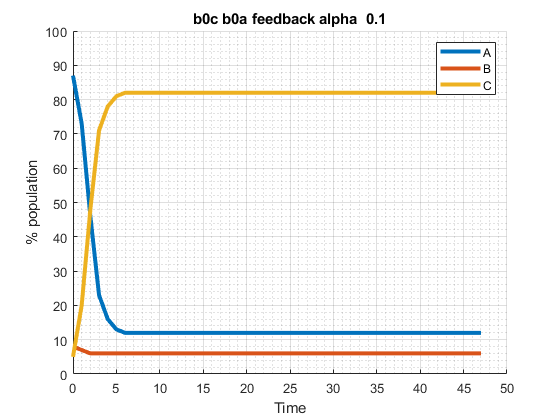

% averaging over all iterations and defining for different values of 'y'
% in this end part of loop

x2A(:,:) = PA_final(:,:,end-5);
x3A = mean(x2A,2);
x4A = std(x2A,0,2);
final_data_A_mean(:,f) = x3A;
final_data_A_std(:,f) = x4A;

x2B(:,:) = PB_final(:,:,end-5);
x3B = mean(x2B,2);
x4B = std(x2B,0,2);
final_data_B_mean(:,f) = x3B;
final_data_B_std(:,f) = x4B;

x2C(:,:) = PC_final(:,:,end-5);
x3C = mean(x2C,2);
x4C = std(x2C,0,2);
final_data_C_mean(:,f) = x3C;
final_data_C_std(:,f) = x4C;

end

## Plotting X(epigenetic feedback switching) vs alpha_AC-alpha_CA

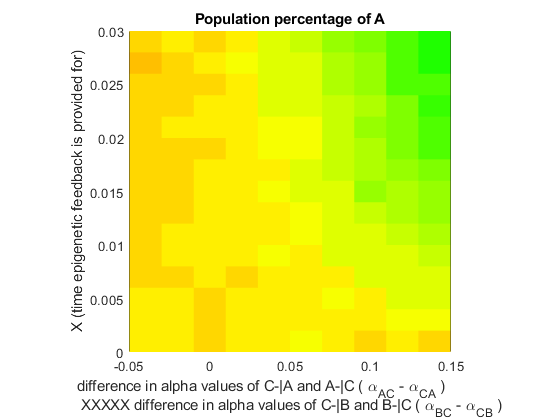


figure()
graphA = pcolor(alpha_ac_ar-alpha_ca_ar,y,final_data_A_mean');
caxis([0 100]);
graphA.EdgeAlpha = 0;
title('Population percentage of A');
xlabel('difference in alpha values of C-|A and A-|C ( \alpha_A_C - \alpha_C_A ) \newline XXXXX difference in alpha values of C-|B and B-|C ( \alpha_B_C - \alpha_C_B )');
ylabel('X (time epigenetic feedback is provided for)');
pbaspect([1 1 1]);
colormap('hsv');

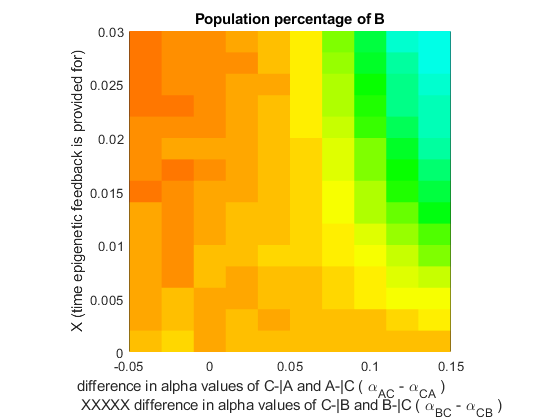


figure()
graphB = pcolor(alpha_ac_ar-alpha_ca_ar,y,final_data_B_mean');
caxis([0 100]);
graphB.EdgeAlpha = 0;
title('Population percentage of B');
xlabel('difference in alpha values of C-|A and A-|C ( \alpha_A_C - \alpha_C_A ) \newline XXXXX difference in alpha values of C-|B and B-|C ( \alpha_B_C - \alpha_C_B )');
ylabel('X (time epigenetic feedback is provided for)');
pbaspect([1 1 1]);
colormap('hsv');

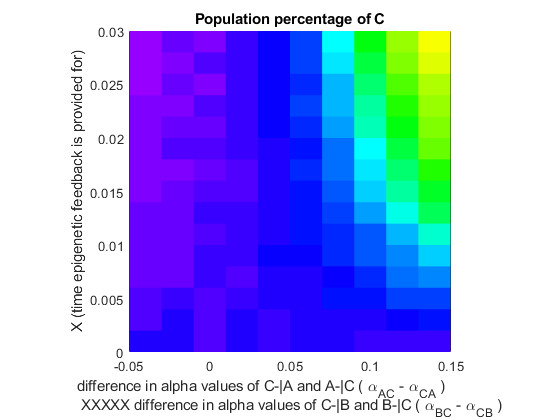


figure()
graphC = pcolor(alpha_ac_ar-alpha_ca_ar,y,final_data_C_mean');
caxis([0 100]);
graphC.EdgeAlpha = 0;
title('Population percentage of C');
xlabel('difference in alpha values of C-|A and A-|C ( \alpha_A_C - \alpha_C_A ) \newline XXXXX difference in alpha values of C-|B and B-|C ( \alpha_B_C - \alpha_C_B )');
ylabel('X (time epigenetic feedback is provided for)');
pbaspect([1 1 1]);
colormap('hsv');

## Plotting X(epigenetic feedback switching) vs alpha_BC-alpha_CB

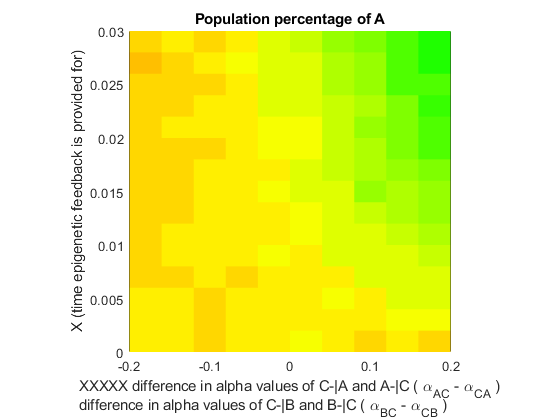


figure()
graphA = pcolor(alpha_bc_ar-alpha_cb_ar,y,final_data_A_mean');
caxis([0 100]);
graphA.EdgeAlpha = 0;
title('Population percentage of A');
xlabel(' XXXXX difference in alpha values of C-|A and A-|C ( \alpha_A_C - \alpha_C_A ) \newline difference in alpha values of C-|B and B-|C ( \alpha_B_C - \alpha_C_B )');
ylabel('X (time epigenetic feedback is provided for)');
pbaspect([1 1 1]);
colormap('hsv');

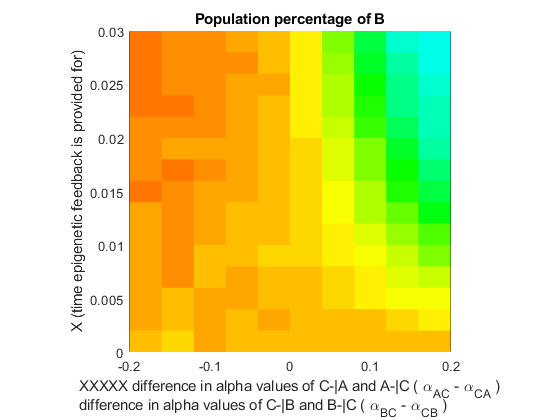


figure()
graphB = pcolor(alpha_bc_ar-alpha_cb_ar,y,final_data_B_mean');
caxis([0 100]);
graphB.EdgeAlpha = 0;
title('Population percentage of B');
xlabel(' XXXXX difference in alpha values of C-|A and A-|C ( \alpha_A_C - \alpha_C_A ) \newline difference in alpha values of C-|B and B-|C ( \alpha_B_C - \alpha_C_B )');
ylabel('X (time epigenetic feedback is provided for)');
pbaspect([1 1 1]);
colormap('hsv');

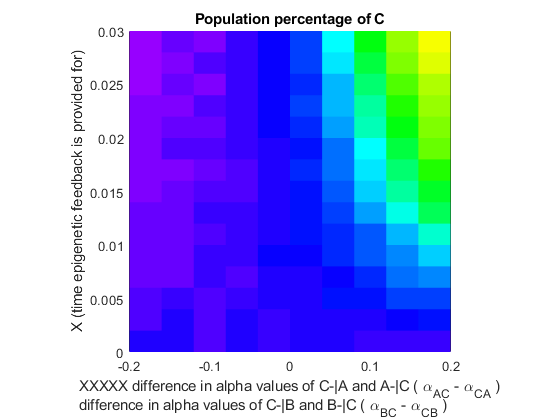


figure()
graphC = pcolor(alpha_bc_ar-alpha_cb_ar,y,final_data_C_mean');
caxis([0 100]);
graphC.EdgeAlpha = 0;
title('Population percentage of C');
xlabel(' XXXXX difference in alpha values of C-|A and A-|C ( \alpha_A_C - \alpha_C_A ) \newline difference in alpha values of C-|B and B-|C ( \alpha_B_C - \alpha_C_B )');
ylabel('X (time epigenetic feedback is provided for)');
pbaspect([1 1 1]);
colormap('hsv');

## Plotting alpha_AC-alpha_CA vs alpha_BC-alpha_CB at fixed X values

% THIS PART REQUIRES EDIT IN INTIAL LOOP DEFINING SO THAT CORRESPONDING
% ALPHA VALUES ARE BROKEN INTO TWO LOOPS RATHER THAN IN ONE AND Y(F)
% VARIABLE CAN BE TAKEN OUT OF LOOP AND FIXED

% figure()
% graphA = pcolor(alpha_ac_ar-alpha_ca_ar,alpha_bc_ar-alpha_cb_ar,final_data_A_mean');
% caxis([0 100]);
% graphA.EdgeAlpha = 0;
% title('Population percentage of A');
% xlabel('difference in alpha values of C-|A and A-|C ( \alpha_C_A - \alpha_A_C )');
% ylabel('difference in alpha values of C-|B and B-|C ( \alpha_C_B - \alpha_B_C )');
% pbaspect([1 1 1]);
% colormap('hsv');
% 
% figure()
% graphB = pcolor(alpha_ac_ar-alpha_ca_ar,alpha_bc_ar-alpha_cb_ar,final_data_B_mean');
% caxis([0 100]);
% graphB.EdgeAlpha = 0;
% title('Population percentage of B');
% xlabel('difference in alpha values of C-|A and A-|C ( \alpha_C_A - \alpha_A_C )');
% ylabel('difference in alpha values of C-|B and B-|C ( \alpha_C_B - \alpha_B_C )');
% pbaspect([1 1 1]);
% colormap('hsv');
% 
% figure()
% graphC = pcolor(alpha_ac_ar-alpha_ca_ar,alpha_bc_ar-alpha_cb_ar,final_data_C_mean');
% caxis([0 100]);
% graphC.EdgeAlpha = 0;
% title('Population percentage of C');
% xlabel('difference in alpha values of C-|A and A-|C ( \alpha_C_A - \alpha_A_C )');
% ylabel('difference in alpha values of C-|B and B-|C ( \alpha_C_B - \alpha_B_C )');
% pbaspect([1 1 1]);
% colormap('hsv');
